# Parameter estimation of TA1415 model

## Open the model

modelName = 'TA1415';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','0')

## Estimation problem

You use measured data to estimate the model parameters.

Input is IPTG concentration (step).

Measured output data is concentation in the culture medium

- OD600

- IPA

Parameters: six kinetic parameters

## Define the estimation experiments

Load the measured data.

outputData = cell(15,1);
for expIdx = 1:15
    outputData{expIdx} = readtable("TA1415Data.xlsx","Sheet",expIdx);
end

Create the input data.

inputTime = [0 6 6 9 9 12 12 15 15 69]';
input = cell(15,1);

for i = 0:4
    input{5*i + 1} = [1 1 1 1 1 1 1 1 1 1]';
    input{5*i + 2} = [0 0 1 1 1 1 1 1 1 1]';
    input{5*i + 3} = [0 0 0 0 1 1 1 1 1 1]';
    input{5*i + 4} = [0 0 0 0 0 0 1 1 1 1]';
    input{5*i + 5} = [0 0 0 0 0 0 0 0 1 1]';
end

inputData = cell(15,1);
for expIdx = 1:15
    inputData{expIdx} = table;
    inputData{expIdx}.Time = inputTime;
    inputData{expIdx}.IPTG = input{expIdx};
end

Create an experiment object to store the measured input/output data. 

Exp = sdo.Experiment(modelName);
% sdo.Experiment object
% The OutputData property and other properties are empty

Create Simulink.SimulationData.Signal objects to store the measured outputs.

% IPTG input
IPTGSignal = Simulink.SimulationData.Signal;
IPTGSignal.Name = 'IPTG';
IPTGSignal.BlockPath = modelName + "/IPTG";
IPTGSignal.PortType  = 'inport';
IPTGSignal.PortIndex = 1;
IPTGSignal.Values    = timeseries(inputData{1}.IPTG,inputData{1}.Time);

Exp.InputData = IPTGSignal; % add the signal object to the experiment

% OD600 output
OD600Signal = Simulink.SimulationData.Signal;
OD600Signal.Name = 'OD600';
OD600Signal.BlockPath = modelName + "/Gain";
OD600Signal.PortType = 'outport';
OD600Signal.PortIndex = 1;
OD600Signal.Values = timeseries(outputData{1}.OD600,outputData{1}.Time);

% Glucose output
% GlucoseSignal = Simulink.SimulationData.Signal;
% GlucoseSignal.Name = 'Glucose';
% GlucoseSignal.BlockPath = modelName + "/Gain2";
% GlucoseSignal.PortType = 'outport';
% GlucoseSignal.PortIndex = 1;
% GlucoseSignal.Values = timeseries(outputData{1}.Glucose,outputData{1}.Time);

% IPA output
IPASignal = Simulink.SimulationData.Signal;
IPASignal.Name = 'IPA';
IPASignal.BlockPath = modelName + "/Demux";
IPASignal.PortType = 'outport';
IPASignal.PortIndex = 5;
IPASignal.Values = timeseries(outputData{1}.IPA,outputData{1}.Time);

Exp.OutputData = [OD600Signal; IPASignal]; % add the signal object to the experiment

Define the five experiments.

Exp = [Exp;Exp;Exp;Exp;Exp;...
        Exp;Exp;Exp;Exp;Exp;...
        Exp;Exp;Exp;Exp;Exp];
for expIdx = 1:15
    Exp(expIdx).InputData.Values = timeseries(inputData{expIdx}.IPTG,inputData{expIdx}.Time);
    Exp(expIdx).OutputData(1).Values = timeseries(outputData{expIdx}.OD600,outputData{expIdx}.Time);
    % Exp(expIdx).OutputData(2).Values = timeseries(outputData{expIdx}.Glucose,outputData{expIdx}.Time);
    Exp(expIdx).OutputData(2).Values = timeseries(outputData{expIdx}.IPA,outputData{expIdx}.Time);
end

## Specify the parameters to estimate

Specify bounds for the parameter values based on the structure of the model.

parameters = readtable("Parameters_TA1415.xlsx");
p = sdo.getParameterFromModel(modelName,parameters.Name);

% the output argument 'p' is a Param.Continuous object
% scaling factor can be specified in the Param.Continuous object

for paramIdx = 1:height(parameters)
    p(paramIdx).Value = parameters.InitialGuess(paramIdx);
    p(paramIdx).Minimum = parameters.Minimum(paramIdx);
    p(paramIdx).Maximum = parameters.Maximum(paramIdx);
    p(paramIdx).Scale = parameters.Scale(paramIdx);
    p(paramIdx).Free = parameters.Free(paramIdx);
end

## Compare the measured output and the simulated output with the initial guess

Set the initial guess of the parameters to the experiment object and simulate. 

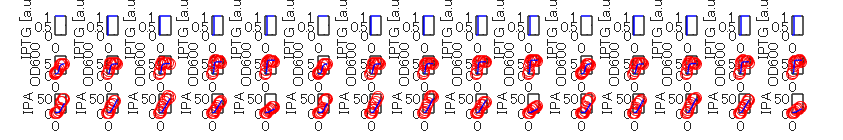

Exp = setEstimatedValues(Exp,p);
figure('Position', [100 100 1500 250]);
t = tiledlayout(3,15,'Padding','Compact','TileSpacing','tight');
t.TileIndexing = 'columnmajor';
for expIdx = 1:15
    plotSimTA1415(Exp,expIdx);
end

Check the objective function.

Simulator = createSimulator(Exp(1));
Error = estimation_Objective(p,Simulator,Exp,1:15,1:2,0);
fx = Error.F'*Error.F

fx = 13.2892

## Configure the simulator and model for Fast Restart

The simulator controls whether the model is simulated using fast restart or not. The `fastRestart` command is used to configure the simulator to use Fast Restart. 

The model uses a variable-step solver, and may not output values at the times in the measured experiment data. To output values at the times of the measured data, use the `set_param` command to specify the model logging output times as a workspace variable. In the estimation objective function, the variable is then used to specify output times to be the same as the measured experiment data. The model `OutputTimes` is set before configuring the simulator for fast restart, as once the model is configured for fast restart, the model logging configuration can not change.

Simulator = createSimulator(Exp(1));
modelName = Simulator.ModelName;
set_param(modelName,'OutputOption','SpecifiedOutputTimes', ...
    'OutputTimes','OutputTimesValues');
% 'OutputTimesValues' will be created in the objective function and assigned to the base
% workspace
Simulator = fastRestart(Simulator,'on');

The simulator can now be used during estimation, and the model will be simulated using fast restart.

## Define the estimation objective function

Create an estimation objective function to evaluate how closely the simulation output, generated using the estimated parameter values, matches the measured data.

Use an anonymous function with one input argument that calls the `cellCultureModel_Objective` function. Pass the anonymous function to `sdo.optimize`, which evaluates the function at each optimization iteration.

lambda = 0;         % regularization parameter
expToUse = 1:15;     % training data set
outputToUse = 1:2;  % two outputs (OD600,IPA)
estFcn = @(p) estimation_Objective(p,Simulator,Exp,expToUse,outputToUse,lambda);

## Estimate the parameters

Use the `sdo.optimize` function to estimate the actuator parameter values and initial state. 

Specify the optimization options. The estimation function `sdoAircraftEstimation_Objective` returns the error residuals between simulated and experimental data and does not include any constraints, making this problem ideal for the `lsqnonlin` solver.

options = sdo.OptimizeOptions;
options.Method = 'lsqnonlin';

Estimate the parameters.

tic
[pOpt,optInfo] = sdo.optimize(estFcn,p,options)


 最適化開始時間 19-Feb-2023 21:42:37

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     16      13.2792            1                                         
    1     33      13.2792       0.4764         14.9
    2     50      9.23517       0.1191         5.68
    3     67      7.49682       0.0792         12.7
    4     84      5.34928       0.1518         6.28
    5    101      4.79181       0.2382         15.4
    6    118      4.54353       0.2146         65.8
    7    135      3.95408       0.1265           30
    8    152      3.80045      0.07863         13.8
    9    169      3.69377       0.1349         32.6
   10    186       3.6668      0.01842         5.65
   11    203      3.66631    6.865e-05        0.731
局所的最小値の可能性があります。

二乗和において、その初期値からの最終的な変化量が
関数の許容誤差値未満であるため、lsqnonlin は停止しました。
 
pOpt(1,1) =
 
       Name: 'k1'
      Value: 0.4772
    Minimum: 0
    Maximum: NaN
       Free: 1
      Scale: 1
       Info: [

optInfo = フィールドをもつ struct :
               F: [369×1 double]
        Jacobian: [1×1 struct]
        exitflag: 3
      iterations: 11
    SolverOutput: [1×1 struct]
           Stats: [1×1 struct]


toc

経過時間は 1586.512622 秒です。


save('pOpt_TA1415_ABC_verify','pOpt')
save('optInfo_TA1415_ABC_veryfy','optInfo')

## Calculate the confidence intervals

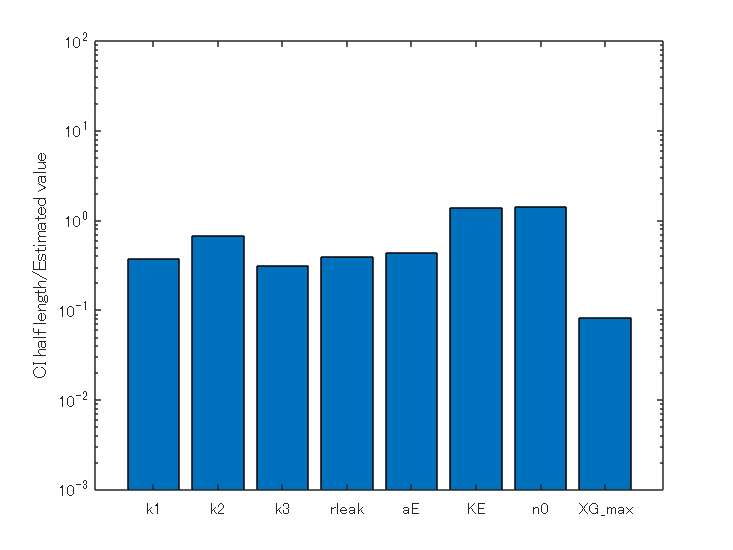

ci_ratio = plotCI(pOpt,optInfo);

## Restore the model

Restore the simulator fast restart settings. This clears the logging and other settings used for the optimization problem. 

Simulator = fastRestart(Simulator,'off');
set_param(modelName,'OutputOption','RefineOutputTimes','OutputTimes','[]');

## Compare the test data set and the simulated output

Update the experiments with the estimated parameter values.

Exp = setEstimatedValues(Exp,pOpt);

Simulate the model updated with the estimated parameter value and compare the simulated output with the experimental data. The model response using the estimated parameter values closely matches the experiment output data.

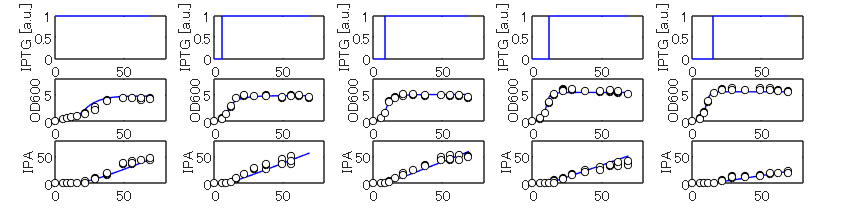

figure('Position', [100 100 1000 250]);
t = tiledlayout(3,5,'Padding','Compact','TileSpacing','tight');
t.TileIndexing = 'columnmajor';
for expIdx = 1:5 % test data set
    plotSimTA1415_stylized(Exp,expIdx);
end

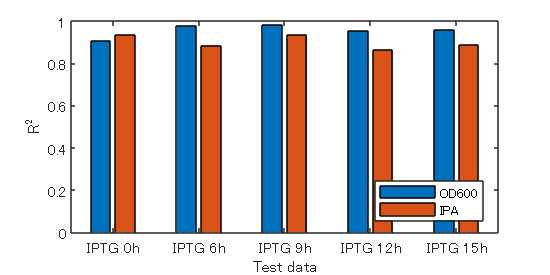

Simulator = createSimulator(Exp(1));
R2 = zeros(15,2);
for expIdx = 1:15 % test data set
    R2(expIdx,:) = rSquared(pOpt,Simulator,Exp,expIdx,1:2);
end

R2_OD600 = R2(:,1);
R2_IPA = R2(:,2);

R2_OD600_mean = mean(reshape(R2_OD600,5,3),2);
R2_IPA_mean = mean(reshape(R2_IPA,5,3),2);

figure('Position', [100 100 400 200]);
b = bar([R2_OD600_mean,R2_IPA_mean]);
xticklabels({'IPTG 0h' 'IPTG 6h' 'IPTG 9h' 'IPTG 12h' 'IPTG 15h'})
xlabel('Test data')
ylabel('R^2')
ylim([0 1])
legend({'OD600' 'IPA'},'Location','Southeast')

sdo.setValueInModel('TA1415',pOpt);

Close the model.

bdclose('cellCultureModel')

*Copyright Tomoki Ohkubo@NAIST*